웹캠 설정

cam = webcam;

훈련한 네트워크(딥러닝) 불러오기

load("netTransfer.mat","netTransfer")

웹캠으로 우유 딥러닝 확인하기 (이미지 1장)

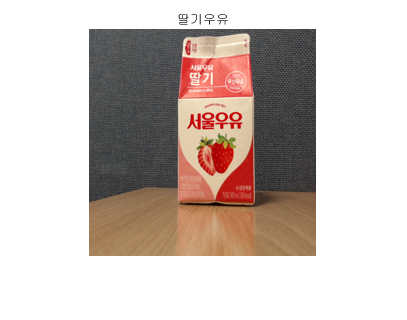

img = snapshot(cam);
img = imresize(img, [227 227]);
label = classify(netTransfer,img);

figure,
imshow(img)
title(label);

실시간으로 딥러닝 실행하기 (이미지 및 바 그래프 표시)

※ 아래 코드를 복사해서 m파일에서 실행해야 한다.

while 1
    img = snapshot(cam);
    img = imresize(img, [227 227]);
    [label, scores] = classify(netTransfer,img);
    
    [~, idx] = sort(scores,'descend');
    idx = idx(4:-1:1);
    classNamesTop = netTransfer.Layers(end).Classes(idx);
    scoresTop = scores(idx);
    
    figure(1),
    subplot(121), imshow(img)
    title(label);
    subplot(122), barh(scoresTop)
    xlim([0 1]);
    title('Top 4 Predictions')
    xlabel('Probability')
    yticklabels(classNamesTop)    
    drawnow;
end
